**1. Example**

1.1 Problem


$$f =a + ab + bt$$


This is a linear w.r.t the variable $t$, but non-linear w.r.t the estimators

 1.2 Generate Data

For study Newton- gauss non-linear LME, we need measurements in real situation, but here we generate a data

clear all;clc
syms a b S
f=@(a,b,S) a+a*b + b*S;
Data =[ ];
for i = 1:10
    Data =[Data ; [i, subs(f, [a,b,S], [1,2,i])] ];
end
Data;

Here the real values to be estimate are  


$$(a,b) = (1,2)$$


1.3 Generation the pseudo Inverse of the Jacobian

H = [diff(f,a)  diff(f,b)];  % gradient w.r.t the estimators
estX =[2;3];                 % initial guess of estimators
Z =[ ];
JA = [ ];
for k = 1:2
    for i = 1:10
        Z=[Z; Data(i,2) - subs(f,[a,b,S],[estX(1), estX(2), Data(i,1)])];
        JA =[JA;subs(H,[a,b,S],[estX(1), estX(2),Data(i,1)])];
    end 
    
  PseJA = inv(JA'*JA)*JA';   % pseudo Inverse
  estX =estX +PseJA*Z;       % next estimator
  estX = double(estX);       % conver to double
  Z=[ ];
  JA =[ ];
 end
 estX 

estX =      1
     2


here we get the real value at the frist step. If you change the initial guess 

1.1 Problem


$$f =a/(b+t)$$


This is a linear w.r.t the variable $t$, but non-linear w.r.t the estimators

 1.2 Generate Data

For study Newton- gauss non-linear LME, we need measurements in real situation, but here we generate a data

clear all;clc
syms a b t
f=@(a,b,t) a/(b+t);
Data =[ ];
for i = 1:10
    Data =[Data ; [i, subs(f, [a,b,t], [1,2,i])] ];
end
Data

$$Data = \left(\begin{array}{cc} 1 & \frac{1}{3}\\ 2 & \frac{1}{4}\\ 3 & \frac{1}{5}\\ 4 & \frac{1}{6}\\ 5 & \frac{1}{7}\\ 6 & \frac{1}{8}\\ 7 & \frac{1}{9}\\ 8 & \frac{1}{10}\\ 9 & \frac{1}{11}\\ 10 & \frac{1}{12} \end{array}\right)$$

Here the real values to be estimate are  


$$(a,b) = (1,1)$$


1.3 Generation the pseudo Inverse of the Jacobian

H = [diff(f,a)  diff(f,b)];  % gradient w.r.t the estimators
estX =[1;1];                 % initial guess of estimators
Z =[ ];
JA = [ ];
for k = 1:3
    for i = 1:10
        Z=[Z; Data(i,2) - subs(f,[a,b,t],[estX(1), estX(2), Data(i,1)])];
        JA =[JA;subs(H,[a,b,t],[estX(1), estX(2),Data(i,1)])];
    end 
    
  PseJA = inv(JA'*JA)*JA';   % pseudo Inverse
  estX =estX +PseJA*Z;       % next estimator
  estX = double(estX);       % conver to double
  Z=[ ];
  JA =[ ];
 end
 estX 

estX =     0.9998
    1.9988


here we get the real value at the frist step. If you change the initial guess 

**2. Example**

https://en.wikipedia.org/wiki/Gauss%E2%80%93Newton_algorithm

1. problem 

In biology an example, the measurement is the rate $R$, function of the concentration, $S$


$$R = \frac{aS}_{b+S}, 

$$


to estiamte $a ,\ b$ with the measurement as 

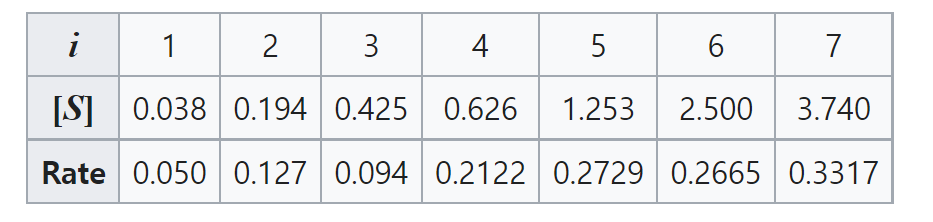

Here is the non-linear w.r.t the variable $S$ and the estimators

2. Procesure

2.1 Data generation

clear all; clc
% Data 
DataS =[0.038;0.194;0.425;0.626;1.253;2.500;...
        3.740];
DataR = [0.050;0.127;0.094;0.2122;0.2729;0.2665;...
        0.3317];   
Data=[DataS DataR]

Data =     0.0380    0.0500
    0.1940    0.1270
    0.4250    0.0940
    0.6260    0.2122
    1.2530    0.2729
    2.5000    0.2665
    3.7400    0.3317


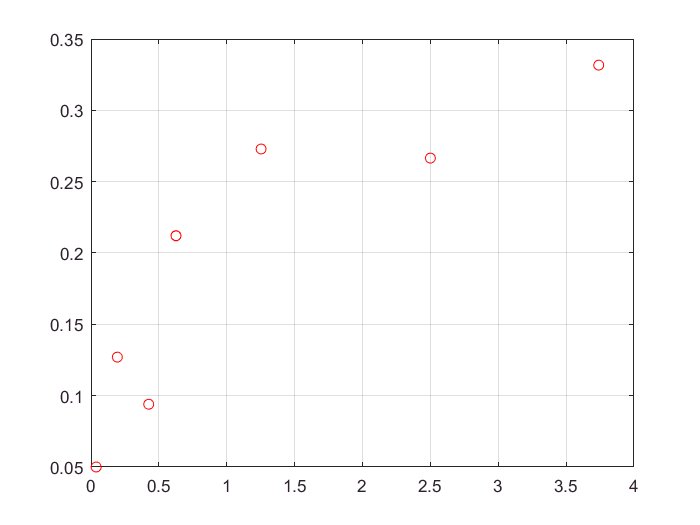

plot(Data(:,1), Data(:,2),'ro');grid on;hold on

2.2 Procesure

  To derive the Jacobian matrix, we need 


$$\frac{\partial R}{ \partial a }, \frac{\partial R}{ \partial b}
$$
 

 Here we use symbolic math 

syms a b S
R = @(a,b,S) a*S/(b + S);
% Gradient 
H = [diff(R,a) diff(R,b)];
% calculate the error with the first estimator
estX =[0.9;0.2];
Z =[ ];
JA = [ ];
for k = 1:5
    for i = 1:7
        Z=[Z; Data(i,2) - subs(R,[a,b,S],[estX(1), estX(2), Data(i,1)])];
        JA =[JA;subs(H,[a,b,S],[estX(1), estX(2),Data(i,1)])];     
    end 
  PseJA = inv(JA'*JA)*JA';  
  estX =estX +PseJA*Z;
  estX = double(estX)
  Z = [ ];
  JA =[ ];
 end

estX =     0.3327
    0.2602


estX =     0.3428
    0.4261


estX =     0.3578
    0.5295


estX =     0.3614
    0.5537


estX =     0.3618
    0.5561
